%[x, fs] = audioread("10sec mese.wav");
%[x, fs] = audioread("moving_in_the_room.wav");
[x, fs] = audioread("music 01.wav");
size(x)

ans =       212073           2


fs

fs = 22050


% defining parameters
x1=x(:,1);
nFft = 512;
segLen= 512;
stepsize = 221;   % this is set to 10ms, ie: 22100Fs /100 = 221
lenx1=length (x1);
nSegs = floor ((lenx1-stepsize)/stepsize);

% cutting signal into frames
frames=zeros(nSegs, segLen);
size(frames)

ans =    958   512



weightFrame = hamming(segLen);

for j=1:nSegs
    midPos = j*stepsize;
    startPos = midPos-stepsize+1;
    endPos = startPos+segLen-1;
    % cutting and weighting the frames
    frames(j, :)=x1(startPos:endPos); %.*weightFrame;
end

% calculate energy of frames
nrgx1=zeros(nSegs,1);
size(nrgx1)

ans =    958     1



for j=1:nSegs
    frame=frames(j,:);
    %frameSquared=frame.*frame;
    %nrgx1(j,1)=sum(frameSquared);
    
    frameAbs = abs(frame);
    nrgx1(j,1)=sum(frameAbs);
    %nrgx1(j,1)=max(frameAbs);
   
end

% plotting signal 
figure(1); clf
subplot(311)
plot(x1)
title('Input signal')

% plotting energy
subplot(312)
plot(nrgx1)
title('Signal energy')

% derivinf onset probabaility
nrg_deriv1 = nrgx1(2:end-1)-nrgx1(1:end-2);
nrg_deriv2 = nrgx1(3:end)-nrgx1(1:end-2);
nrg_deriv3 = nrg_deriv2 - nrg_deriv1;

% cutting of negative values, ie. "off"-sets.
nrg_deriv1(nrg_deriv1<0) = 0;
nrg_deriv2(nrg_deriv2<0) = 0;
nrg_deriv3(nrg_deriv3<0) = 0;

%  plotting onset probabaility
subplot(313);
hold on
plot(nrg_deriv1, 'r')
plot(nrg_deriv2, 'b')
plot(nrg_deriv3, 'g')
title('onset detection')

% deriving VAD from energy
vadx1=zeros(nSegs, 1);

sorted=sort(nrgx1);
quantileHere = floor(nSegs/2)

quantileHere = 479

vadTh=sorted(quantileHere)

vadTh = 32.6797

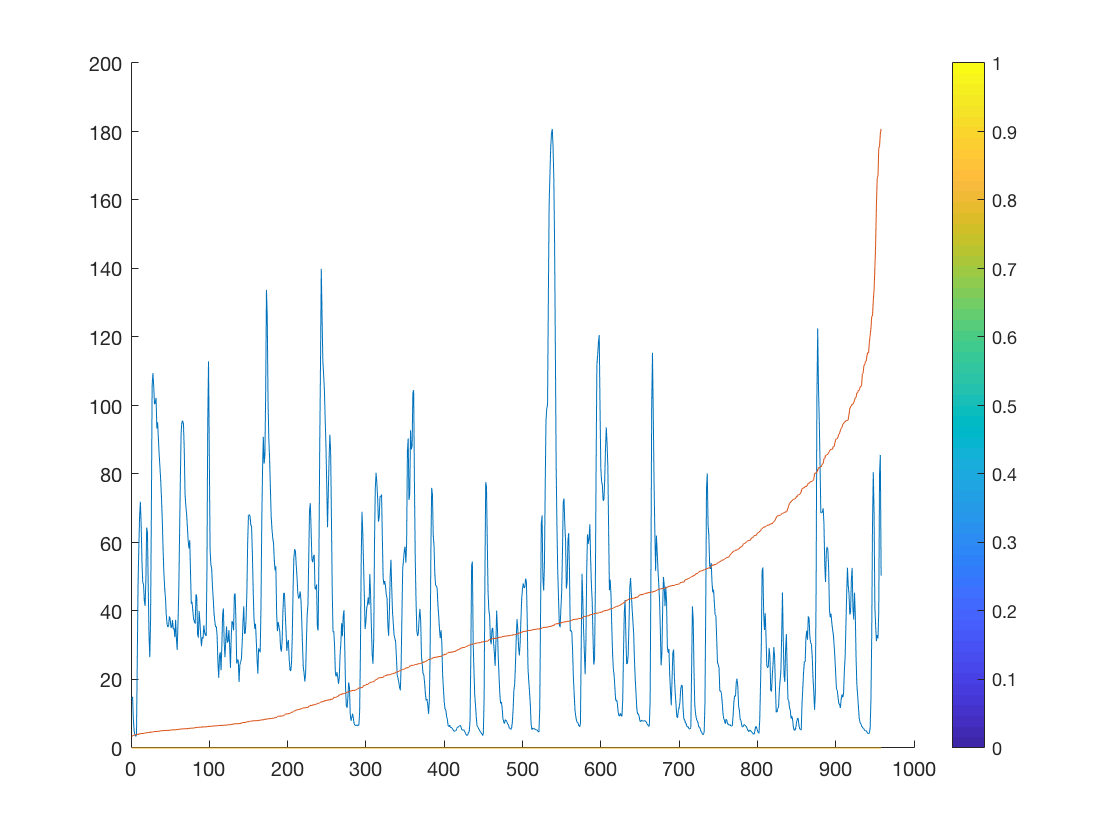

vadx1=nrgx1>vadTh;

figure(3)
hold on
plot(nrgx1)
plot(sort(nrgx1))
%plot(hist(nrgx1))
plot (vadx1/1000)
colorbar


sound(x1, fs)

## BPM extraction

nrg_seg_len = 300; % here 100 means 1 sec.

from = 1 

from = 1

till = nrg_seg_len

till = 300

nrg1 = nrg_deriv3(from:till);

from = 1+ nrg_seg_len 

from = 301

till = 2*nrg_seg_len

till = 600

nrg2 = nrg_deriv3(from:till);

from = 1+ 2*nrg_seg_len 

from = 601

till = 3*nrg_seg_len

till = 900

nrg3 = nrg_deriv3(from:till);

%nrg1 = nrgx1(1:200);
%nrg2 = nrgx1(201:400);
%nrg3 = nrgx1(401:600);

## look at BPM curve

% autocorraletion of envelope inside 3sec audio:
nrg_corr1= xcorr (nrg1, nrg1);
nrg_corr2= xcorr (nrg2, nrg2);
nrg_corr3= xcorr (nrg3, nrg3);

% zeroing around zero lag:
from = nrg_seg_len-10;
till = nrg_seg_len+10;
nrg_corr1(from:till) = 0;
nrg_corr2(from:till) = 0;
nrg_corr3(from:till) = 0;

% would be a good idea to mirror around the center 
% and add each mirrorewd halve once more
nrg_sum3x=nrg_corr1+nrg_corr2+nrg_corr3;

## plotting BPM estimaiton

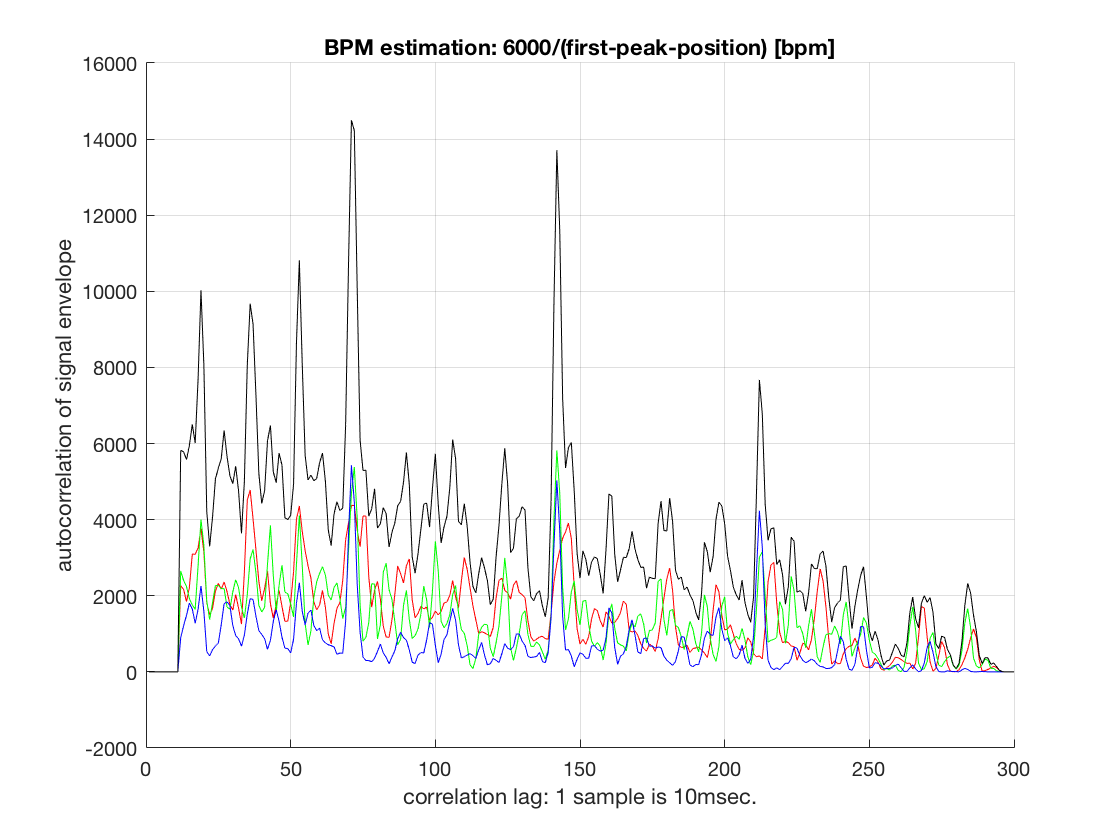

figure(2); clf
hold on; 
title ('BPM estimation: 6000/(first-peak-position) [bpm]')
plot(nrg_corr1(nrg_seg_len:end),'r')
plot(nrg_corr2(nrg_seg_len:end),'g')
plot(nrg_corr3(nrg_seg_len:end),'b')
plot(nrg_sum3x(nrg_seg_len:end),'k')
grid
xlabel('correlation lag: 1 sample is 10msec.')
ylabel('autocorrelation of signal envelope')